%calculating the mean first passage time analytically/numerically 
%to investigate effect of branch migration domain length on DNA/RNA toehold
%exchange kinetics including spontaneous incumbent dissociation 

%b = 20 %define branch migration domain length 
g = 2 %define invader toehold length

g = 2

g2 = 4 %define incumbent toehold length

g2 = 4


R = 1.987/1000 % universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGrd = -0.3*R*temp

dGrd = -0.1777

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(1,30)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 30)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(1, 30)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through branch migration domain lengths
for b = 10:40
    bg2 = b + g2 %calculate branch migration domain + incumbent toehold length

    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp(dGbp/(R*temp));
    k_C1f = k_bp * exp(-(dGbm + dGp - dGrd)/(R*temp))
    k_Cf = k_bp * exp(-(dGbm - dGrd)/(R*temp))
    k_Cr = k_bp * exp(-dGbm/(R*temp));
    k_DC = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_DEij = k_bp * exp((dGbp + dGrd)/(R*temp));
    k_DEji = k_bp;
    k_EF = k_bp * exp((dGbp + dGrd)/(R*temp));
    k_FE = 0
    k_FF = 1    
    
    %create arrays of forward and reverse transition rates
    Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
    Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    
    %define spontaneous incumbent dissociation rates
    Koff = [repmat(0, [1, g2+1])]; 
    for n = g2+1:bg2-1
        Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp - dGrd))/(R*temp))]);
    end
    Koff = horzcat(Koff, [repmat(0, [1, g+1])])
    
    Pn_jN_1 = zeros(1,numel(Kf))
    jn_jN_1 = zeros(1,numel(Kf))
    Pn_jN_1 (1) = 0;
    jn_jN_1 (1) = 1;
        
    %calculate flux between each state
    for Pn = 2:numel(Kf)
        Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
        jn_jN_1(Pn) = jn_jN_1(Pn-1) + Koff(Pn) * Pn_jN_1(Pn);
    end
        
    first_pass_time (b-9) = (1/jn_jN_1(end-1))*sum(Pn_jN_1) %calculate first passage time
    k_eff (b-9) = 1/(first_pass_time (b-9)*(5*10^-8));%calculate effective rate constant
    prob_unbound(b-9) = Pn_jN_1(end)/sum(Pn_jN_1) %calculate prob of being in unbound state
end

bg2 = 14

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    1.9653         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 15

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    1.9653    2.6789         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 16

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    1.9653    2.6789    3.6422         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 17

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    1.9653    2.6789    3.6422    4.9426         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 18

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    1.9653    2.6789    3.6422    4.9426    6.6979         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 19

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    1.9653    2.6789    3.6422    4.9426    6.6979    9.0672         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 20

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+06 *

    0.1965    0.2679    0.3642    0.4943    0.6698    0.9067    1.2266         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 21

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.1965    0.2679    0.3642    0.4943    0.6698    0.9067    1.2266    1.6583         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 22

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.1965    0.2679    0.3642    0.4943    0.6698    0.9067    1.2266    1.6583    2.2411         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 23

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.1965    0.2679    0.3642    0.4943    0.6698    0.9067    1.2266    1.6583    2.2411    3.0277         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 24

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.1965    0.2679    0.3642    0.4943    0.6698    0.9067    1.2266    1.6583    2.2411    3.0277    4.0896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 25

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.1965    0.2679    0.3642    0.4943    0.6698    0.9067    1.2266    1.6583    2.2411    3.0277    4.0896    5.5230         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 26

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.1965    0.2679    0.3642    0.4943    0.6698    0.9067    1.2266    1.6583    2.2411    3.0277    4.0896    5.5230    7.4579         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 27

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0197    0.0268    0.0364    0.0494    0.0670    0.0907    0.1227    0.1658    0.2241    0.3028    0.4090    0.5523    0.7458    1.0070         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 28

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0197    0.0268    0.0364    0.0494    0.0670    0.0907    0.1227    0.1658    0.2241    0.3028    0.4090    0.5523    0.7458    1.0070    1.3595         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 29

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0007


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0197    0.0268    0.0364    0.0494    0.0670    0.0907    0.1227    0.1658    0.2241    0.3028    0.4090    0.5523    0.7458    1.0070    1.3595    1.8354         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 30

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0197    0.0268    0.0364    0.0494    0.0670    0.0907    0.1227    0.1658    0.2241    0.3028    0.4090    0.5523    0.7458    1.0070    1.3595    1.8354    2.4778         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 31

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0197    0.0268    0.0364    0.0494    0.0670    0.0907    0.1227    0.1658    0.2241    0.3028    0.4090    0.5523    0.7458    1.0070    1.3595    1.8354    2.4778    3.3450         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 32

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0197    0.0268    0.0364    0.0494    0.0670    0.0907    0.1227    0.1658    0.2241    0.3028    0.4090    0.5523    0.7458    1.0070    1.3595    1.8354    2.4778    3.3450    4.5155         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0


bg2 = 33

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0197    0.0268    0.0364    0.0494    0.0670    0.0907    0.1227    0.1658    0.2241    0.3028    0.4090    0.5523    0.7458    1.0070    1.3595    1.8354    2.4778    3.3450    4.5155    6.0956         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0


bg2 = 34

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0197    0.0268    0.0364    0.0494    0.0670    0.0907    0.1227    0.1658    0.2241    0.3028    0.4090    0.5523    0.7458    1.0070    1.3595    1.8354    2.4778    3.3450    4.5155    6.0956    8.2284         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0


bg2 = 35

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0020    0.0027    0.0036    0.0049    0.0067    0.0091    0.0123    0.0166    0.0224    0.0303    0.0409    0.0552    0.0746    0.1007    0.1360    0.1835    0.2478    0.3345    0.4516    0.6096    0.8228    1.1107         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0


bg2 = 36

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0020    0.0027    0.0036    0.0049    0.0067    0.0091    0.0123    0.0166    0.0224    0.0303    0.0409    0.0552    0.0746    0.1007    0.1360    0.1835    0.2478    0.3345    0.4516    0.6096    0.8228    1.1107    1.4994         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0


bg2 = 37

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0020    0.0027    0.0036    0.0049    0.0067    0.0091    0.0123    0.0166    0.0224    0.0303    0.0409    0.0552    0.0746    0.1007    0.1360    0.1835    0.2478    0.3345    0.4516    0.6096    0.8228    1.1107    1.4994    2.0240         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0


bg2 = 38

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0020    0.0027    0.0036    0.0049    0.0067    0.0091    0.0123    0.0166    0.0224    0.0303    0.0409    0.0552    0.0746    0.1007    0.1360    0.1835    0.2478    0.3345    0.4516    0.6096    0.8228    1.1107    1.4994    2.0240    2.7321         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0


bg2 = 39

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0020    0.0027    0.0036    0.0049    0.0067    0.0091    0.0123    0.0166    0.0224    0.0303    0.0409    0.0552    0.0746    0.1007    0.1360    0.1835    0.2478    0.3345    0.4516    0.6096    0.8228    1.1107    1.4994    2.0240    2.7321    3.6880         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0


bg2 = 40

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0020    0.0027    0.0036    0.0049    0.0067    0.0091    0.0123    0.0166    0.0224    0.0303    0.0409    0.0552    0.0746    0.1007    0.1360    0.1835    0.2478    0.3345    0.4516    0.6096    0.8228    1.1107    1.4994    2.0240    2.7321    3.6880    4.9783         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0


bg2 = 41

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0020    0.0027    0.0036    0.0049    0.0067    0.0091    0.0123    0.0166    0.0224    0.0303    0.0409    0.0552    0.0746    0.1007    0.1360    0.1835    0.2478    0.3345    0.4516    0.6096    0.8228    1.1107    1.4994    2.0240    2.7321    3.6880    4.9783    6.7200         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0


bg2 = 42

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0020    0.0027    0.0036    0.0049    0.0067    0.0091    0.0123    0.0166    0.0224    0.0303    0.0409    0.0552    0.0746    0.1007    0.1360    0.1835    0.2478    0.3345    0.4516    0.6096    0.8228    1.1107    1.4994    2.0240    2.7321    3.6880    4.9783    6.7200    9.0711         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0


bg2 = 43

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0017    0.0022    0.0030    0.0041    0.0055    0.0075    0.0101    0.0136    0.0184    0.0248    0.0334    0.0452    0.0610    0.0823    0.1111    0.1499    0.2024    0.2732    0.3688    0.4978    0.6720    0.9071    1.2245


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


bg2 = 44

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0017    0.0022    0.0030    0.0041    0.0055    0.0075    0.0101    0.0136    0.0184    0.0248    0.0334    0.0452    0.0610    0.0823    0.1111    0.1499    0.2024    0.2732    0.3688    0.4978    0.6720    0.9071    1.2245


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


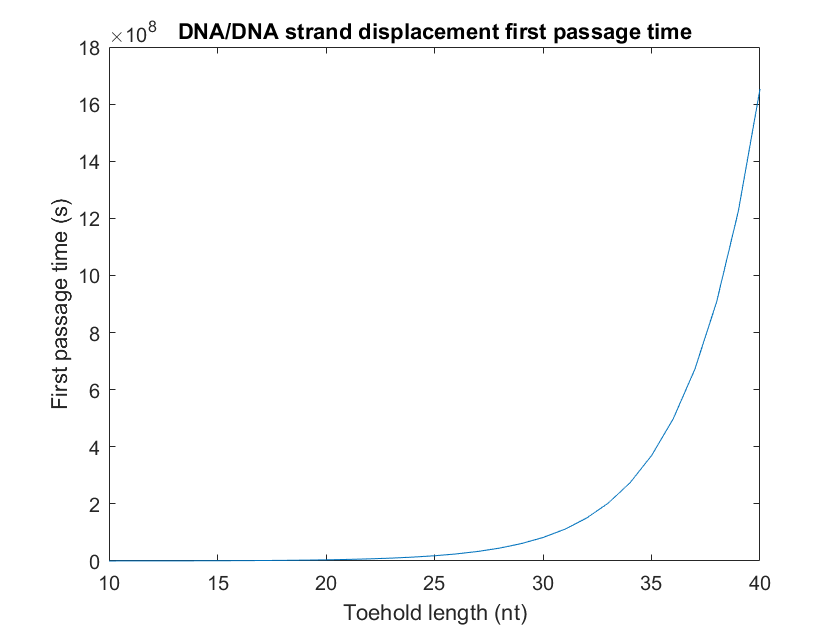

plot(10:40, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

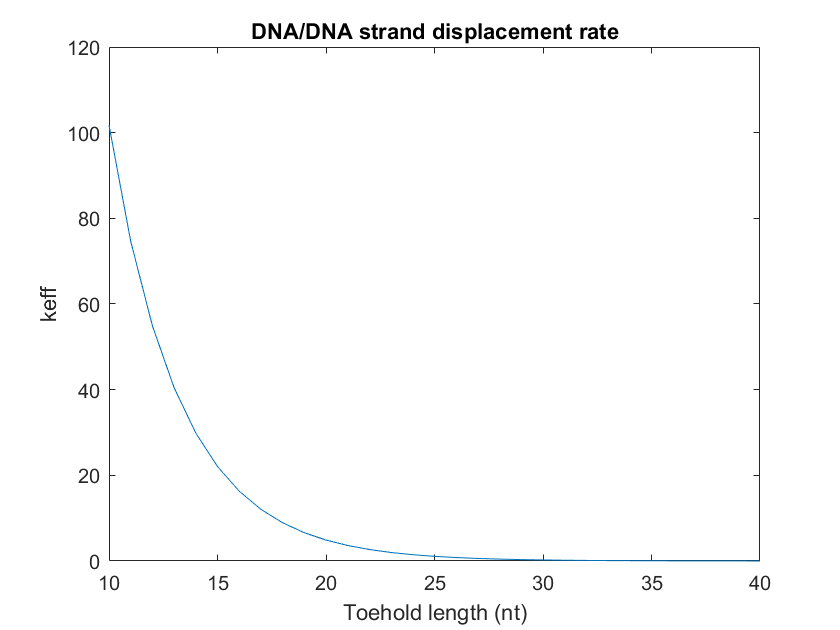


plot(10:40, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')

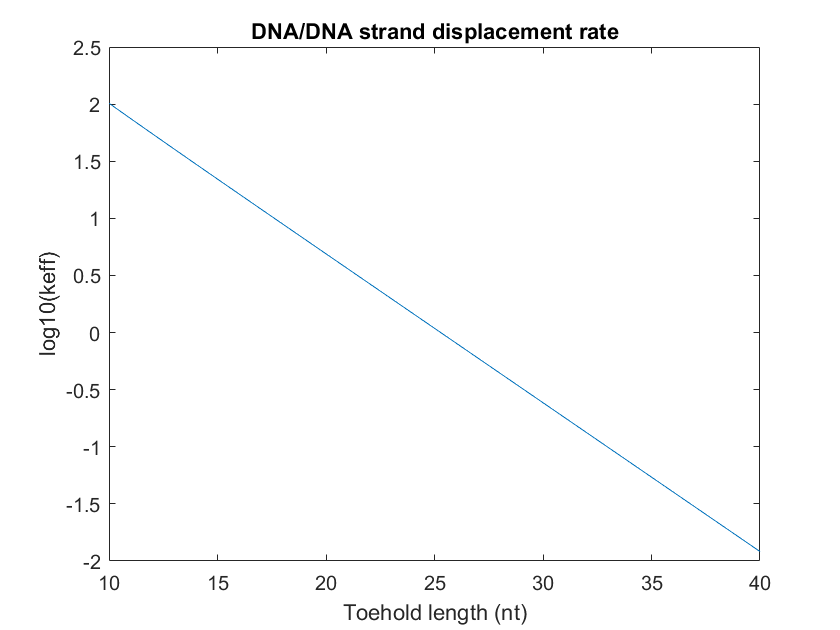


plot(10:40, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate')  